# Simulate system with no input: Van Der Pol Oscillator 

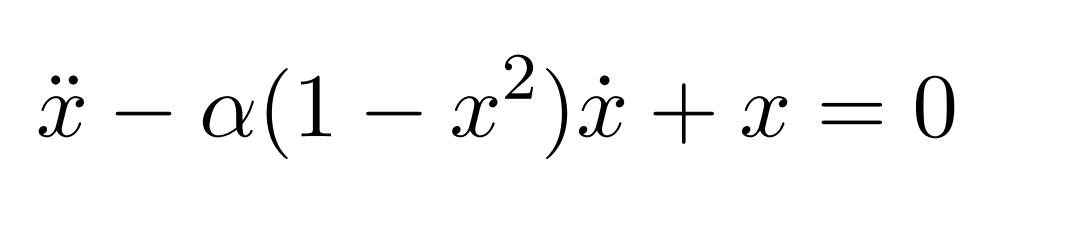

#### Write in standard-form: 

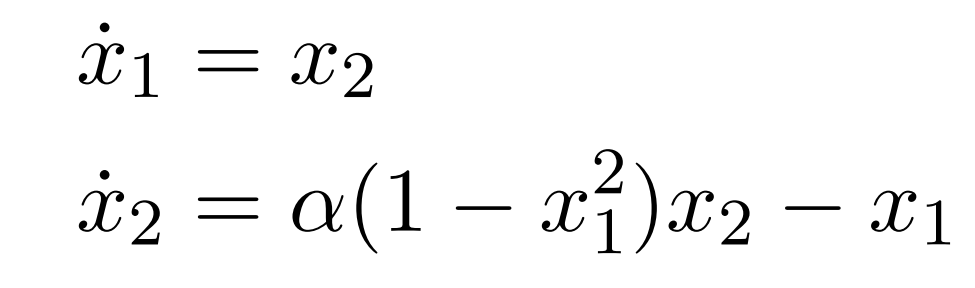

Define paramters: 

global alpha  %define as global to be able use inside simulation function 
alpha =2 
Tfinal=20; % simulation time 

ODE function: 

function dxdt = Van_oscillator(t,x)
global alpha
    dx1=x(2);
    dx2=alpha*(1-x(1)^2)*x(2)-x(1);
    dxdt = [dx1;dx2];
end

Solve and plot:

trange=[0,Tfinal];
x0=[1;1]; %initial condition
[t,x] = ode45(@(t,x)Van_oscillator(t,x), trange, x0); % solve ode 
figure %open figure 
hold on 
plot (x(:,1),x(:,2))%Plot x vs xdot 
xlabel("x")
xlabel("xdot")
hold off 

# Simulate system with input: simple pendulum

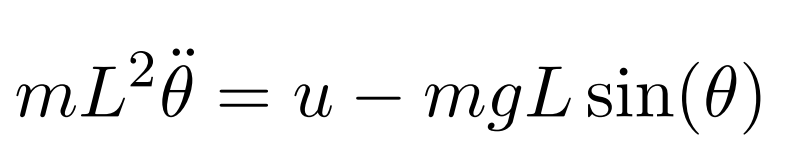

Let: 

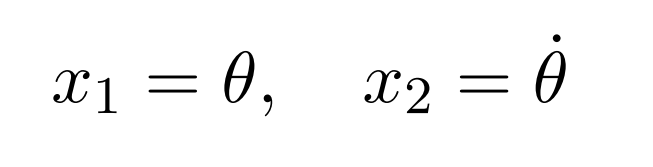

Define global parameters: 

global m L g
m=.2;
L=.4;
g=9.8;

Define function that generates a sinusoidal input given the magnitude and frequency: 


function u= input(t)
mag=.2;
omega=.1;
u=mag*sin(omega*t);
end 

ODE function: 

function dxdt = Pendulum(t,x)
global m L g
    dx1=x(2);
    dx2=(input(t)-m*g*L*sin(x(1)))/(m*L^2);
    dxdt = [dx1;dx2];
end

Solve and plot:

trange=[0,Tfinal];
x0=[1;1]; %initial condition
[t,x] = ode45(@(t,x)Pendulum(t,x), trange, x0); % solve ode 

figure %open figure 
plot (t,x(:,1)) %Plot first state vs time 
xlabel("Time")
legend("theta")

figure 
plot (t,x(:,2)) %Plot second state vs time 
xlabel("Time")
legend("thetadot")

